# Ejercicio N°5

clear;clc;

Se definen simbólicas las variables

syms t vc1(t) vc2(t) il1(t) R1 R2 L1 C1 C2;

Se plantean las ecuaciones y se obtienen las matrices de la forma generalizada

M=[C1 0 0; 0 C2 0; 0 0 L1]

$$M = \left(\begin{array}{ccc} C_{1} & 0 & 0\\ 0 & C_{2} & 0\\ 0 & 0 & L_{1} \end{array}\right)$$

N=[1/R1 0 1; 0 1/R2 -1; -1 1 0]

$$N = \left(\begin{array}{ccc} \frac{1}{R_{1}} & 0 & 1\\ 0 & \frac{1}{R_{2}} & -1\\ -1 & 1 & 0 \end{array}\right)$$

u=[0;0;0]; 


$$u=\left(\matrix{0\cr0\cr0}\right)$$


Se expresan las matrices de la forma normalizada

A=-1.*(M\N)

$$A = \left(\begin{array}{ccc} -\frac{1}{C_{1}\,R_{1}} & 0 & -\frac{1}{C_{1}}\\ 0 & -\frac{1}{C_{2}\,R_{2}} & \frac{1}{C_{2}}\\ \frac{1}{L_{1}} & -\frac{1}{L_{1}} & 0 \end{array}\right)$$

Se definen las variables de estado

x=[vc1;vc2;il1]

$$x(t) = \left(\begin{array}{c} {\mathrm{vc}}_{1}\left(t\right)\\ {\mathrm{vc}}_{2}\left(t\right)\\ {\mathrm{il}}_{1}\left(t\right) \end{array}\right)$$

Expresando el sistema en forma diferencial

odes = diff(x) == A*x

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}{\mathrm{vc}}_{1}\left(t\right)=-\frac{{\mathrm{il}}_{1}\left(t\right)}{C_{1}}-\frac{{\mathrm{vc}}_{1}\left(t\right)}{C_{1}\,R_{1}}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{2}\left(t\right)=\frac{{\mathrm{il}}_{1}\left(t\right)}{C_{2}}-\frac{{\mathrm{vc}}_{2}\left(t\right)}{C_{2}\,R_{2}}\\ \frac{\partial }{\partial t}{\mathrm{il}}_{1}\left(t\right)=\frac{{\mathrm{vc}}_{1}\left(t\right)}{L_{1}}-\frac{{\mathrm{vc}}_{2}\left(t\right)}{L_{1}} \end{array}\right)$$

Reemplazando los valores de los componentes

clear C1 C2 L1 R1 R2;
syms C1 C2;
R1=1;R2=1;C1=1;C2=1;L1=2;
A=subs(A);
odes = diff(x) == A*x;

Definiendo las condiciones iniciales y tiempo de simulacion

vc01=1/2;
vc02=1/2;
il0=1/2;
ti=0;
tf=10;
Xant=[vc01;vc02;il0];
constantes=x(0)==Xant;
[vc1Sol(t), vc2Sol(t), il1Sol(t)] = dsolve(odes,constantes);

# Tensión sobre R2

simplify(vc2Sol(t))

$$ans = \frac{{\mathrm{e}}^{-t}}{2}-\frac{\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3\,\sqrt{{\mathrm{e}}^{t}}}$$

# Respuesta temporal vR2(t)

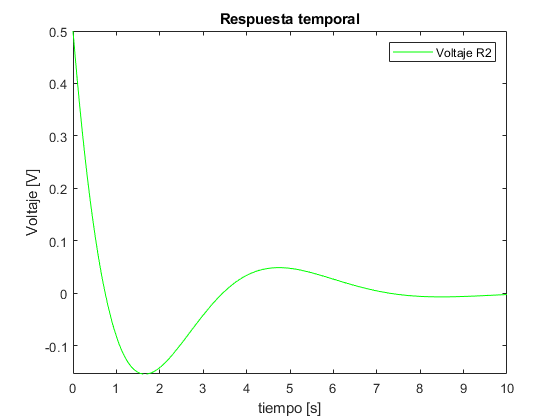

clf;
fplot(vc2Sol,[ti,tf],'-g')
title('Respuesta temporal')
xlabel('tiempo [s]')
ylabel('Voltaje [V]')
legend({'Voltaje R2'})